# **DEMO_03:**   **Simulate** Dynamic equations of motion of Slider crank mechanism

`Bradley Horton : 25-Feb-2022, bhorton@mathworks.com`

**Overview:**

- In the script [`bh_DEMO_02_dynamics_derivation_SLIDER_CRANK.mlx`](matlab:open('bh_DEMO_02_dynamics_derivation_SLIDER_CRANK.mlx')) we derived the dynamic Equations of motion for our Slider Crank Mechanism.

- We'll now numerically solve these Equations of motion using Simulink.

- We will also compare the results of our Brain derived model, against the results produced by an alternate way (using Simscape Multibody) of modelling the mechanism 

Recall the system being studied:

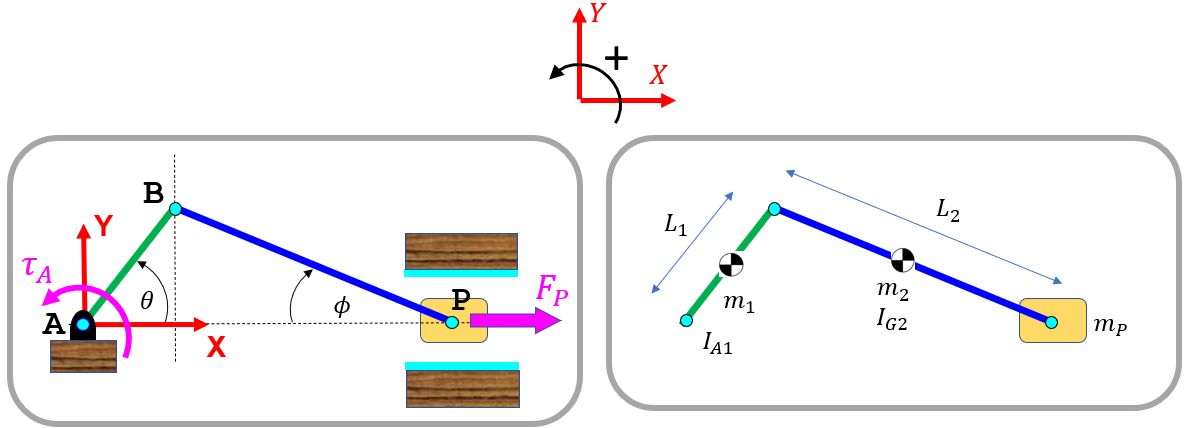

### 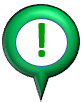 ASSUMPTIONS:

- Links $\textrm{AB}$, $\textrm{BP}$ and the cylinder head are all rectangular prisms

### Geometry and Inertia parameters:

Let's define some numeric values for our Slider Crank mechanism.

:  Pick some length values for links $\textrm{AB}\;\left(L_1 \right)$ and  $\textrm{BP}\;\left(L_2 \right)$ .... just make sure that $L_1 <L_2$

params.L_1       = 0.2;        % (m) - length of link AB
params.L_2       = 0.75;        % (m) - length of link BP  
assert(params.L_1 < params.L_2, "###_ERROR: - Hey, we need to have L1 < L2")

: Pick some viscous damping co-efficients at point $A$ and at the piston wall

params.b_A       = 0.01 ;     % (N.m.s/rad)
params.b_P       = 0.01 ;  % (N.s/m)

And other Geometry and inertia parameters are:

params.hy        = 0.01;       % (m) - the Y direction height of the links
params.tz        = 0.01;       % (m) - thickness of links into the page
params.density   = 7700;                               % (kg/m^3) 
params.volume1   = params.L_1 * params.hy * params.tz; % (m^3)
params.volume2   = params.L_2 * params.hy * params.tz; % (m^3)
params.m_1       = params.volume1 * params.density;   % (kg)
params.m_2       = params.volume2 * params.density;   % (kg)
params.L_P       = 0.05;          % (m) 
params.hyP       = 0.03;          % (m) 
params.volumeP   = params.L_P * params.hyP * params.tz; % (m^3)
params.m_P       = params.volumeP * params.density    ;% (kg)
params.L1_dims   = [params.L_1, params.hy,  params.tz];
params.L2_dims   = [params.L_2, params.hy,  params.tz];
params.LP_dims   = [params.L_P, params.hyP, params.tz];

Calculate the inertia of** Link 2** about a $Z\;\textrm{axis}$ passing through the **center of mass **$\textrm{G2}$ (eg: see [**HERE**](https://en.wikipedia.org/wiki/List_of_moments_of_inertia))

- 
$$I_{\textrm{G2}} \;\;=\;\;\frac{m_2 }{12}\ldotp \left(L_{2X}^2 \;\;+\;\;L_{2Y}^2 \;\right)$$


params.I_G2      = params.m_2*(params.L_2^2 + params.hy^2)/12;

Calculate the inertia of **Link 1** about a $Z\;\textrm{axis}$ passing through the **pivot point **$\mathit{\mathbf{A}}$ (using the parallel axis theorem):

- 
$$I_{\textrm{A1}} \;\;=\;\;m_{1\;} \ldotp {\left(\frac{L_{1X} }{2}\right)}^2 \;\;+\;\;I_{\textrm{G1}} \;\;\;\;\;\;\;$$


params.I_A1      =  params.m_1*(params.L_1/2)^2    +    ...
                    params.m_1*(params.L_1^2 + params.hy^2)/12   ;

## Initial Conditions:

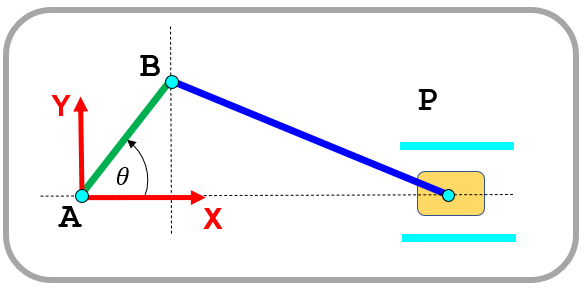

What is the initial angle $\left(\theta \right)$ and angular velocity $\left(\dot{\theta} \right)$ for link $\textrm{AB}$

IC.theta_0         =   deg2rad(30);  % (rad)
IC.theta_dot_0     =   deg2rad(10);  % (rad/sec)

Recall, :

- 
$$L_1 \ldotp \sin \left(\theta \right)\;\;=\;\;L_2 \ldotp \sin \left(\phi \right)$$


- 
$$L_1 \ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;\;=\;\;L_2 \ldotp \cos \left(\phi \right)\ldotp \dot{\phi}$$


IC.phi_0           = asin(  (params.L_1/params.L_2) * sin(IC.theta_0)  );
IC.phi_dot_0       = params.L_1*cos(IC.theta_0)*IC.theta_dot_0 / (params.L_2 * cos(IC.phi_0));

##  Open and Run the Simulink model:

- Click on the button below to open the Simulink model:

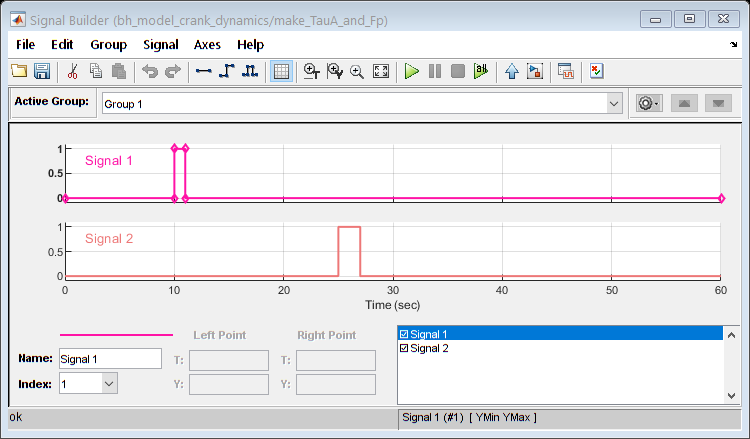

  open_system("bh_model_crank_dynamics")

When the Simulink model appears, 

- click the **Run icon**(see picture below) inside the Simulink model - this will simulate the model for 45 seconds

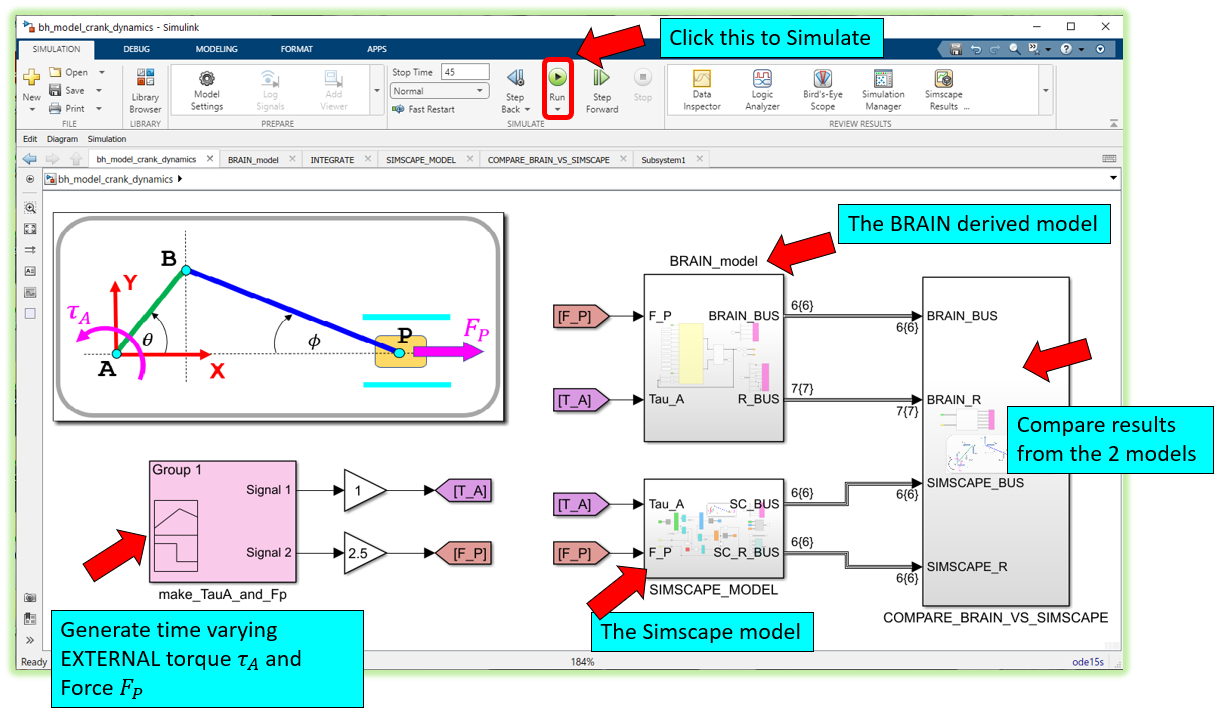

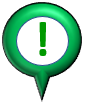  **So what happened ?**

- The Simulink file was simulated for 45 seconds.

- This Simulink file contains both our **BRAIN derived model **and also a 2nd way of modelling the Slider Crank using Simscape Multibody, aka the **Simscape model** - I hope the two different modelling approaches produce the same results !!

- The **Simscape model** produces the CAD like animation viewer.

- The block named `make_TauA_and_Fp` produces the time varying Torque $\left(\tau_A \right)$ and Force $\left(F_P \right)$ that is applied to the Slider Crank.  The time series of these 2 signals is shown below - they are rectangular pulse signals.  The applied Torque $\left(\tau_A \right)$ has a magnitude of $1\;\left(N\ldotp m\right)$.  The applied Force $\left(F_P \right)$ has a magnitude of $2\ldotp 5\;\left(N\right)$

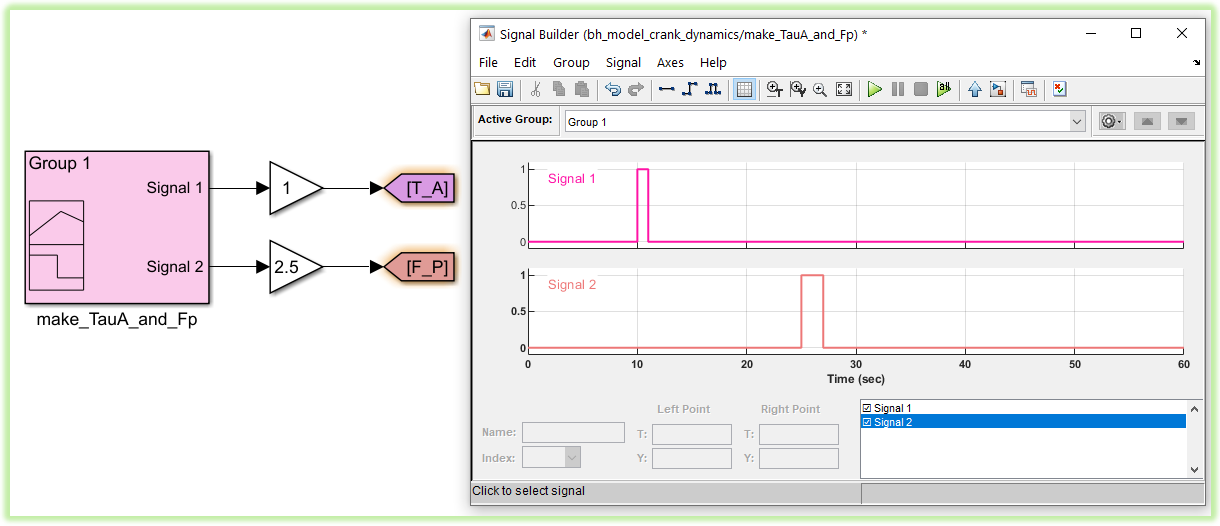

 **Explore the simulation results**

- Double click on the **COMPARE_BRAIN_VS_SIMSCAPE** subsystem

- You'll now see 2 PINK oscilliscope blocks that you can open by (again) double clicking on them

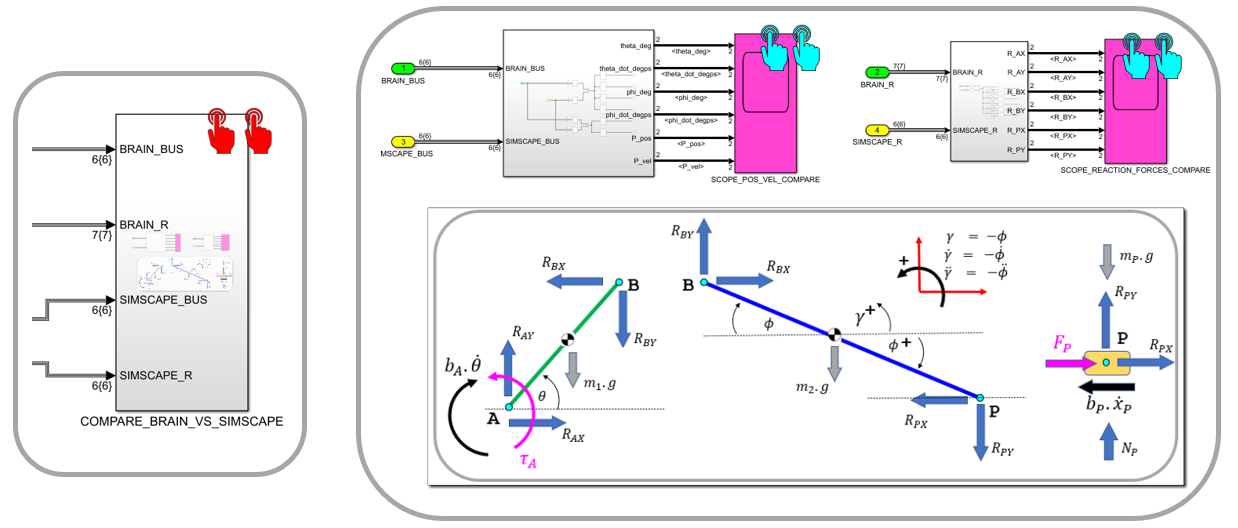

- The **SCOPE_POS_VEL_COMPARE** scope, plots the following signals: 

-    $\Longrightarrow \;\;\;\;\;\;\;\left\lbrack \begin{array}{cccccc}
\theta  & \dot{\theta}  & \phi  & \dot{\phi}  & x_P  & {\dot{x} }_P 
\end{array}\right\rbrack$, and on each axis both the BRAIN and SIMSCAPE results are shown - they are very very similar

- The **SCOPE_REACTION_FORCES_COMPARE** scope, plots the following signals:

- $\Longrightarrow \;\;\;\;\;\;\left\lbrack \begin{array}{cccccc}
R_{\textrm{AX}}  & R_{\textrm{AY}}  & R_{\textrm{BX}}  & R_{\textrm{BY}}  & R_{\textrm{PX}}  & R_{\textrm{PY}} 
\end{array}\right\rbrack$, and on each axis both the BRAIN and SIMSCAPE results are shown - they are very very similar